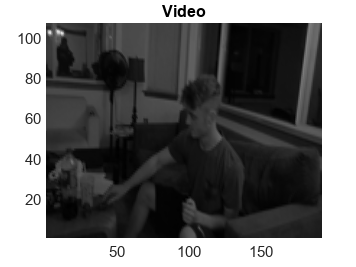

close all
clear all
clc

test=[' Test 1 '];

%video display
vid=read(VideoReader('01040017Trim.MP4'));
vid=vid(:,:,:,1:2:end);
frame=size(vid);
res=[frame(1), frame(2)]/10;
frame=frame(4);
dt=12/frame;
for i=[1:frame]
video(:,:,i)=imresize(flipud(double(rgb2gray(vid(:,:,:,i)))), res);
end


figure
for i=[1:frame]
pcolor(video(:,:,i)), colormap(gray), shading interp
pause(dt)
end
title(['Video'])




%% Construct X and X'

X=[];
for i=[1:frame-1]
dum=video(:,:,i);
X=[X, dum(:)];
end
X

X =    55.5848   56.8110   58.8426   65.2150   71.9367   62.3180   66.1580   44.3142   35.2854   34.2946   34.1701   34.1339   34.3765   34.3634   33.9722   33.2382   33.2073   44.4474   45.7647   44.7536   43.2923   42.1866   43.7864   46.0068   46.3539   46.8273   47.1499   48.2619   48.2385   50.3572   51.4393   51.4233   51.3940   51.7469   51.7483   52.7489   52.5527   52.3422   51.4144   52.5550   53.0575   53.2610   53.9837   54.8168   56.2499   56.2079   56.4195   56.9035   60.2116   59.9285
   55.3765   58.2797   60.8438   67.5735   71.4964   71.8126   67.2442   48.7198   34.5964   33.2260   34.2540   34.0526   34.5818   34.8678   33.1793   32.4411   35.0301   41.3375   41.6070   41.2774   41.1068   40.6643   41.1655   43.4710   44.7952   45.3095   47.9861   48.2738   48.9511   50.1575   51.1722   51.9164   51.7765   51.9152   52.4037   52.4737   52.4368   52.0768   50.4860   51.6366   53.4282   56.0721   58.5961   64.0435   68.9469   69.0047   68.1327   69.5348   71.4439   71


X_tild=[];
for i=[2:frame]
dum=video(:,:,i);
X_tild=[X_tild, dum(:)];
end
X_tild

X_tild =    56.8110   58.8426   65.2150   71.9367   62.3180   66.1580   44.3142   35.2854   34.2946   34.1701   34.1339   34.3765   34.3634   33.9722   33.2382   33.2073   44.4474   45.7647   44.7536   43.2923   42.1866   43.7864   46.0068   46.3539   46.8273   47.1499   48.2619   48.2385   50.3572   51.4393   51.4233   51.3940   51.7469   51.7483   52.7489   52.5527   52.3422   51.4144   52.5550   53.0575   53.2610   53.9837   54.8168   56.2499   56.2079   56.4195   56.9035   60.2116   59.9285   59.3002
   58.2797   60.8438   67.5735   71.4964   71.8126   67.2442   48.7198   34.5964   33.2260   34.2540   34.0526   34.5818   34.8678   33.1793   32.4411   35.0301   41.3375   41.6070   41.2774   41.1068   40.6643   41.1655   43.4710   44.7952   45.3095   47.9861   48.2738   48.9511   50.1575   51.1722   51.9164   51.7765   51.9152   52.4037   52.4737   52.4368   52.0768   50.4860   51.6366   53.4282   56.0721   58.5961   64.0435   68.9469   69.0047   68.1327   69.5348   71.4439   71.7569

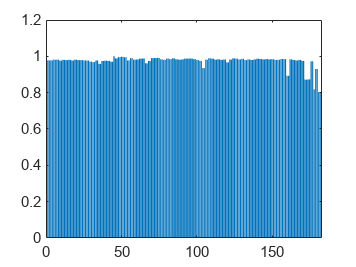





%% DMD

[U, S, V]=svd(X, 'econ');
A_tild=(U')*X_tild*V*inv(S);
[W,D]=eig(A_tild);
phi=U*W;



%% Reconstruct Video
bar(abs(diag(D)))

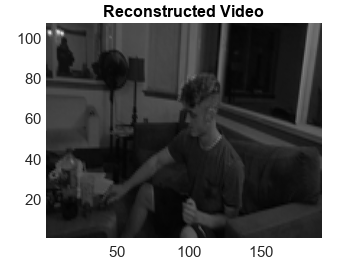

dum=diag(D);
Omega=zeros(size(D));
for i=[1:frame-1]
Omega(i,i)=log(dum(i));
Omega(i,i)=Omega(i,i)/(dt);
end

b=phi\X(:,1);
t=(1:frame);
X_recon_whole=[];

for i=[1:frame-1]
X_recon_whole=[X_recon_whole, phi*D.^i*b];
end

%% Play Reconstructed Video 
figure
for i=[1:frame-1]
dum=abs(reshape(X_recon_whole(:,i), res));
pcolor(dum), colormap(gray), shading interp
pause(dt)
end
title(['Reconstructed Video'])

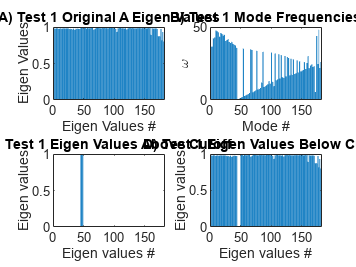



figure
subplot(2,2,1)
bar(abs(diag(D)))
title(['A)', test, 'Original A Eigen Values'])
ylabel('Eigen Values'); xlabel('Eigen Values #'); 
hold on

subplot(2,2,2)
bar(abs(diag(Omega)))
title(['B)', test, 'Mode Frequencies'])
ylabel('\omega'); xlabel('Mode #');  
hold on

low_cutoff=1;
D_low=D;
D_low(abs(Omega) > low_cutoff)=0;

subplot(2,2,3);
bar(abs(diag(D_low)))
title(['C)', test, 'Eigen Values Above Cutoff'])
ylabel('Eigen values'); xlabel('Eigen values #'); 
hold on 


high_cutoff=1;
D_high=D;
D_high(abs(Omega) <= high_cutoff)=0;

subplot(2,2,4);
bar(abs(diag(D_high)))
title(['D)', test, 'Eigen Values Below Cutoff'])
ylabel('Eigen values'); xlabel('Eigen values #'); 
hold on

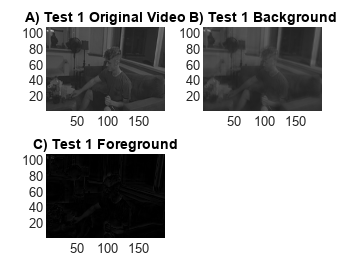



%% Reconstruct Video
X_recon_back=[];
for i=[1:frame-1]
X_recon_back=[X_recon_back, phi*D_low.^i*b];
end

X_recon_fore=[];
for i=[1:frame-1]
X_recon_fore=[X_recon_fore, phi*D_high.^i*b];
end


%% View Original/Background/Foreground
figure
for i=[1:frame-1]

dum1=abs(reshape(X_recon_whole(:,i), res));
subplot(2,2,1)
pcolor(dum1), colormap(gray), shading interp
caxis([0, 255]);
title(['A)', test, 'Original Video'])

dum2=abs(reshape(X_recon_back(:,i), res));
subplot(2,2,2)
pcolor(dum2), colormap(gray), shading interp
caxis([0, 255]);
title(['B)', test, 'Background'])

dum3=abs(reshape(X_recon_fore(:,i), res));
subplot(2,2,3)
pcolor(dum3), colormap(gray), shading interp
caxis([0, 255]);
title(['C)', test, 'Foreground'])

pause(0.01)
end